## **Section 1: *****Feeling the data***

### **Load the data**

load data_country

%extract every col (feature) in variables
%health factors
child_mort = Countrydata(:,1);
health = Countrydata(:,3);
life_exp = Countrydata(:,7);
fertility = Countrydata(:,8);

%socioeconomic factors
exports = Countrydata(:,2);
imports = Countrydata(:,4);
income = Countrydata(:,5);
inflation = Countrydata(:,6);
gdpp = Countrydata(:,9);

**Determine the type of every column**

class(child_mort) %child mortality

ans = 'double'

class(health) %health

ans = 'double'

class(life_exp) %life expectancy

ans = 'double'

class(fertility) %total fertility

ans = 'double'


class(exports) %exports

ans = 'double'

class(imports) %imports

ans = 'double'

class(income) %income

ans = 'double'

class(inflation) %inflation

ans = 'double'

class(gdpp) %GDPP

ans = 'double'

**Determine the range of values for every feature**

%range = max - min
mins = min(Countrydata);
maxs = max(Countrydata);
range = max(Countrydata) - min(Countrydata);

**See the statistics of the data (mean, stdv)**

means = mean(Countrydata);
stdv = std(Countrydata);

**Create the hist for each feature to see its distribution**

%{
% Divide the figure into a 5x4 grid of subplots
for i = 1:9
    subplot(5,4,i)
    histogram(Countrydata(:,i)) % Plot histogram of i-th feature
end
hold off
%}

%{
subplot(5,4,1)
hist_mort = histogram(child_mort);
subplot(5,4,2)
hist_health = histogram(health);
subplot(5,4,3)
hist_life = histogram(life_exp);
subplot(5,4,4)
hist_fert = histogram(fertility);

subplot(5,4,5)
hist_export = histogram(exports);
subplot(5,4,6)
hist_import = histogram(imports); 
subplot(5,4,7)
hist_income = histogram(income); 
subplot(5,4,8)
hist_infl = histogram(inflation);
subplot(5,4,9)
hist_gdpp = histogram(gdpp);
%}


%%%% NEW FEATURE %%%%%
%fs_nom = Countrydata(:,9)+(Countrydata(:,9).*Countrydata(:,6));
%final_data = [fs1,fs2,fs3,fs5,fs_nom]

## Standarization

**Boxplots to see if there are outliers**

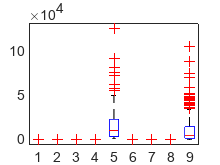

boxplot(Countrydata)

**Compute corr coeff to see linear dependance of each feature**

cor = corrcoef(Countrydata);

**Standard score normalization (NEW EDITED VERSION)**

features = [child_mort,exports,health,imports,income,inflation,life_exp,fertility,gdpp];
zscored_features = zscore(features);


## **Min-Max with standard score normalization (NEW EDITED VERSION)**

%%% NEEEWWW %%%
% min max για τα ssnorm
%d = new max = 1
%c = new min = 0
normalized_features = (zscored_features - min(zscored_features)) ./ (max(zscored_features) - min(zscored_features));


## Min Max without standard score normalization

%min-max feature scaling normalization
%d = new max = 1
%c = new min = 0
minmax_only = (features - min(features)) ./ (max(features) - min(features));

**Frame with all features scaled with standard score and min max (NEW EDITED VERSION)**

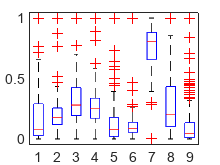

new_corr_coeff = corrcoef(normalized_features);
boxplot(normalized_features)

Box-plot features only with standard score

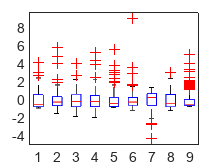

boxplot(zscored_features)

Box-plots only with min max normalization

%new_corr_coeff = corrcoef(features);
boxplot(minmax_only)

**Remove features**

% remove fertility and imports
%final = [child_mor,exp,health,incm,infl,life_exp,gdpp];

**Remove features from std_features**

%remove imports, inflation(keep gdpp), 
%final_std = [ssnorm_childmort,ssnorm_exp,ssnorm_health,ssnorm_income,ssnorm_fert ,ssnorm_gdpp];


**New features (NEW EDITED VERSION)**

earnings = exports - imports;


## Section 2: *CLUSTERING*

### ELBOW to determine the number of clusters

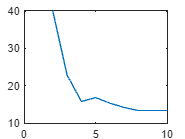

final = normalized_features;

%elbow
% Compute J_m and plot J_m versus m
[l,N]= size(final);
nruns=10;
m_min=2;
m_max=10;
J_m=[];
for m=m_min:m_max
    J_temp_min=inf;
    for t=1:nruns
        rand('seed',100*t)
        theta_ini=rand(l,m);
        [theta,bel,J]= k_means(final,theta_ini);
        if(J_temp_min>J)
            J_temp_min=J;
        end
    end
    J_m=[J_m J_temp_min];
end
m=m_min:m_max;
figure(2), plot(m,J_m)

**K-means (4 clusters)**

final = transpose(normalized_features);
k = 4;  
%[l, N] = size(final_data_T);
%rand('seed', 0)
theta_ini = rand_data_init(final, k);
[theta,bel,J]=k_means(final,theta_ini);

**Plot results**

2D

gscatter(final(5,:), final(1,:), bel)
xlabel('Fertility') 
ylabel('Child mortality') 

3D

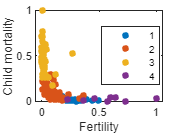

colormap([1 0 0; 0 0 0; 0 1 0; 0.5 0 0.5])

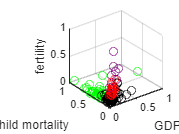

scatter3(final(6,:), final(1,:),final(5,:),'CData',bel)
xlabel('GDPP')
ylabel('child mortality')
zlabel('fertility')

**Plot results 2**

2D

gscatter(final(5,:), final(4,:), bel) 
xlabel('Fertility') 
ylabel('Income') 

3D

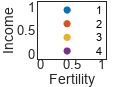

colormap([1 0 0; 0 0 0; 0 1 0; 0.5 0 0.5])

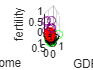

scatter3(final(6,:), final(4,:),final(5,:),'CData',bel)
xlabel('GDPP')
ylabel('Income')
zlabel('fertility')

**Plot results 3**

2D

gscatter(final(4,:), final(3,:), bel) 
xlabel('Income') 
ylabel('Health') 

3D

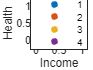

colormap([1 0 0; 0 0 0; 0 1 0; 0.5 0 0.5])

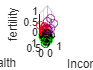

scatter3(final(4,:), final(3,:),final(5,:),'CData',bel)
xlabel('Income')
ylabel('Health')
zlabel('fertility')

**Plot results 4**

2D

gscatter(final(6,:), final(3,:), bel) 
xlabel('GDPP') 
ylabel('Health') 

3D

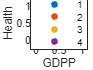

colormap([1 0 0; 0 0 0; 0 1 0; 0.5 0 0.5])

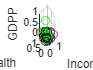

scatter3(final(4,:), final(3,:),final(6,:),'CData',bel)
xlabel('Income')
ylabel('Health')
zlabel('GDPP')

**Attempt to plot all features as k-means clusters**

With themselved

Two together

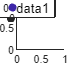

%{
% Create a new figure window with a specified size
figure('Position', [0, 0, 71, 65])

% Add a title to the figure
title('K-means clustering scatterplots', 'FontSize', 47, 'Position', [0.433, 0.91])

% Loop over the rows in the data matrix
for j = 1:size(final, 2)
    for i = 1:size(final, 2)
        
        % Create a subplot
        subplot(size(final, 2), size(final, 2), i+1+j*size(final, 2))
        
        % Plot a scatterplot using the specified data and colors
        scatter(final(:,i+1), final(:,j+1), [], final(:,end), 'filled')
        
        % Add a legend to the plot
        legend('Location', 'best', 'FontSize', 10)
    end
end

%}